clc;
clear;

% Define system parameters
Gb = 4.5; 
Ib = 15;
P1 = 0; 
P2 = 0.025; 
P3 = 0.000013;
V = 12; 
n = 5.54/60;
Xe = 0; 
Ge = 0; 
Ie = 0; 
Ue = 0;

% State-space matrices
A = [-P1 - Xe, -Ge - Gb, 0;
      0, -P2, P3;
      0, 0, -n];
B = [1, 0;
     0, 0;
     0, 1/V];
C = [1, 0, 0];
D = [0, 0];

% Convert state-space to transfer function
syms s;
[num_U, den_U] = ss2tf(A, B, C, D, 2);
[num_D, den_D] = ss2tf(A, B, C, D, 1);
G_open_loop_U = minreal(tf(num_U, den_U));
G_open_loop_D = minreal(tf(num_D, den_D));

% Symbolic representation of transfer functions
numerator_U = poly2sym(num_U, s);
denominator_U = poly2sym(den_U, s);
[num_D_simplified, den_D_simplified] = tfdata(G_open_loop_D, 'v');
numerator_D = poly2sym(num_D_simplified, s);
denominator_D = poly2sym(den_D_simplified, s);
tf_U = vpa(numerator_U / denominator_U, 6);
tf_D = vpa(numerator_D / denominator_D, 6);

% Display transfer functions
disp('Transfer Function Regarding To Input:');

Transfer Function Regarding To Input:


disp(tf_U);

$$-\frac{0.000004875}{s^{3}+0.117333\,s^{2}+0.00230833\,s}$$

disp('Transfer Function Regarding To Noise:');

Transfer Function Regarding To Noise:


disp(tf_D);

$$\frac{1}{s}$$

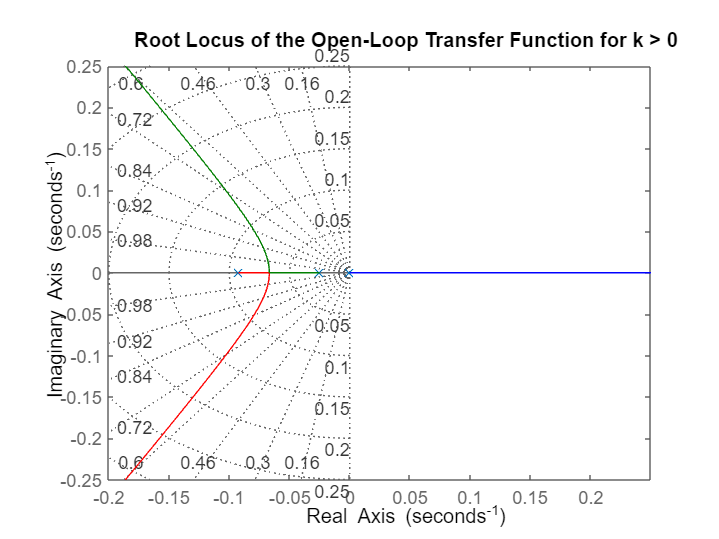


% Root locus analysis
figure;
rlocus(G_open_loop_U);
sgrid;
title('Root Locus of the Open-Loop Transfer Function for k > 0');

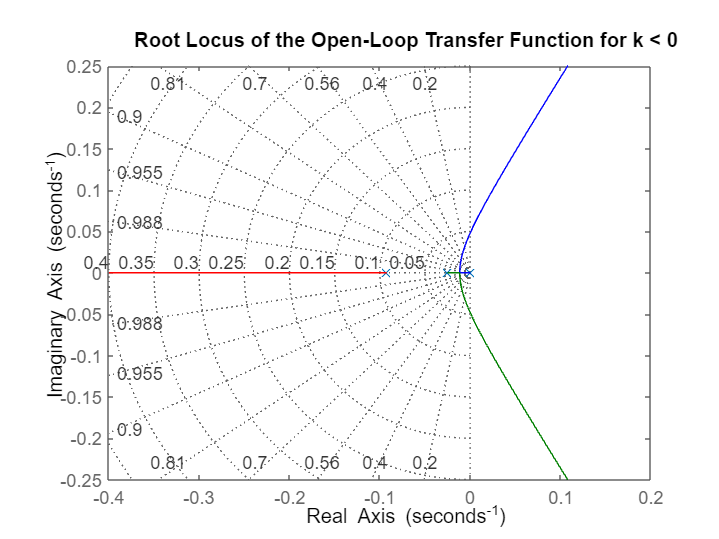

xlabel('Real Axis');
ylabel('Imaginary Axis');

figure;
rlocus(-G_open_loop_U);
title('Root Locus of the Open-Loop Transfer Function for k < 0');
xlabel('Real Axis');
ylabel('Imaginary Axis');
grid on;

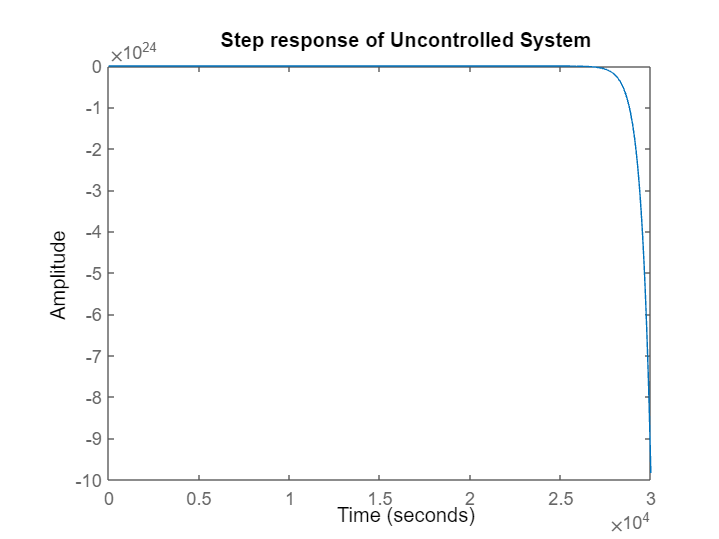


% Closed-loop step response
G_closed_loop_U = feedback(G_open_loop_U, 1);
step(G_closed_loop_U);
title('Step response of Uncontrolled System');


% Critical gain calculation
delta_closed_loop = @(K) den_U + K * [zeros(1, length(num_U) - length(den_U)), num_U];
K_values = linspace(-1000, 1000, 1000000);
for K = K_values
    poles = roots(delta_closed_loop(K));
    if any(abs(real(poles)) < 1e-5)
        critical_gain = K;
        break;
    end
end
disp(['Gain at which system becomes oscillatory: K = ', num2str(critical_gain)]);

Gain at which system becomes oscillatory: K = -55.6231


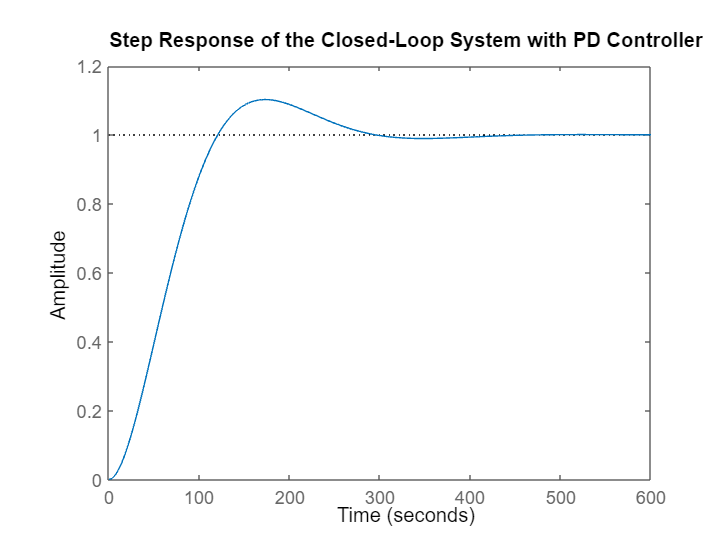


% PD controller design
Kp = -9.2091;
Kd = -116.37;
PD = tf([Kd, Kp], 1);
PD_open_loop_U = PD * G_open_loop_U;
PD_closed_loop_U = feedback(PD_open_loop_U, 1);

% Step response with PD controller
step(PD_closed_loop_U);
title('Step Response of the Closed-Loop System with PD Controller');

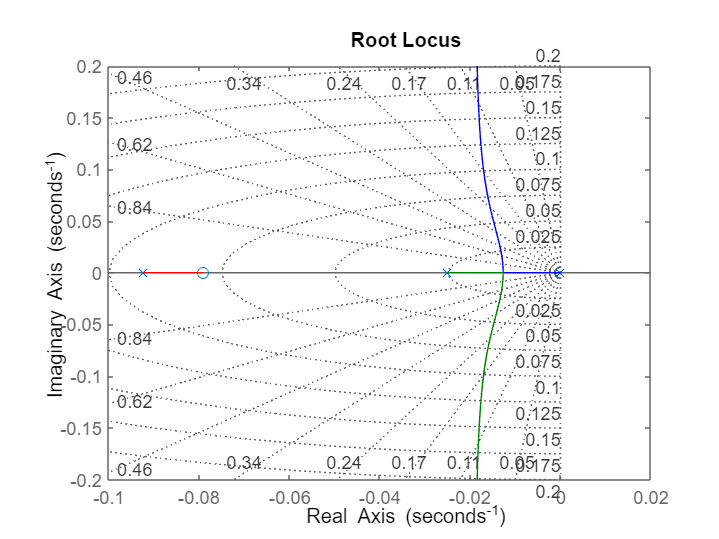

rlocus(PD_open_loop_U);
sgrid;


% Performance metrics
info = stepinfo(PD_closed_loop_U);
overshoot = info.Overshoot; 
settling_time = info.SettlingTime;
disp(['Overshoot: ', num2str(overshoot), '%']);

Overshoot: 10.2633%


disp(['Settling Time: ', num2str(settling_time), ' s']);

Settling Time: 264.994 s


steady_state_value = dcgain(PD_closed_loop_U);
ess = 1 - steady_state_value;
disp(['Steady-State Error: ', num2str(ess)]);   

Steady-State Error: 0


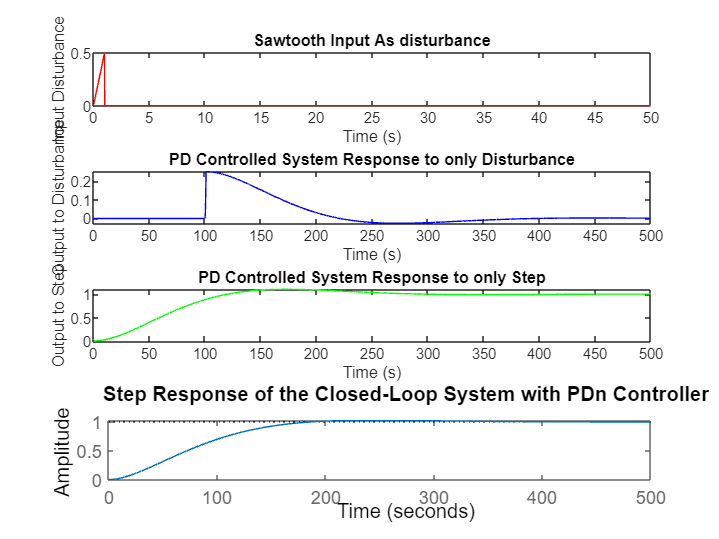


% Time domain analysis with disturbance
time = 0:0.01:500;
time_plot = 0:0.01:50;
input_D_plot = 0.5 * time_plot;
input_D_plot(time_plot > 1) = 0;
Ts_D = 100;
Te_D = Ts_D + 1;
input = ones(size(time));
input_D = 0.5 * time - 0.5 * Ts_D;
input_D(time < Ts_D) = 0;
input_D(time > Te_D) = 0;
PD_closed_loop_D = minreal((G_open_loop_D) / (1 + PD * G_open_loop_U));
[output_D_PD, ~] = lsim(PD_closed_loop_D, input_D, time); 
[output_U_PD, ~] = lsim(PD_closed_loop_U, input, time);
output_total_PD = output_U_PD + output_D_PD;

% Plot results
figure;
subplot(4, 1, 1);
plot(time_plot, input_D_plot, 'r');
xlabel('Time (s)');
ylabel('Input Disturbance');
title('Sawtooth Input As disturbance');

subplot(4, 1, 2);
plot(time, output_D_PD, 'b');
xlabel('Time (s)');
ylabel('Output to Disturbance');
title('PD Controlled System Response to only Disturbance');

subplot(4, 1, 3);
plot(time, output_U_PD, 'g');
xlabel('Time (s)');
ylabel('Output to Step');
title('PD Controlled System Response to only Step');

subplot(4, 1, 4);
plot(time, output_total_PD, 'k');
xlabel('Time (s)');
ylabel('Total Output');
title('PD Controlled System Response to Step Input and Sawtooth Input');

% New PD controller design
Kdd = -111.23;
Kpp = -6.3915;
PDn = tf([Kdd, Kpp], 1);
PDn_open_loop_U = PDn * G_open_loop_U;
PDn_closed_loop_U = feedback(PDn_open_loop_U, 1);

% Step response with new PD controller
step(PDn_closed_loop_U);
title('Step Response of the Closed-Loop System with PDn Controller');


% Performance metrics
info = stepinfo(PDn_closed_loop_U);
overshoot = info.Overshoot; 
settling_time = info.SettlingTime;
disp(['Overshoot: ', num2str(overshoot), '%']);

Overshoot: 2.978%


disp(['Settling Time: ', num2str(settling_time), ' s']);

Settling Time: 302.2041 s


steady_state_value = dcgain(PDn_closed_loop_U);
ess = 1 - steady_state_value;
disp(['Steady-State Error: ', num2str(ess)]);

Steady-State Error: 0


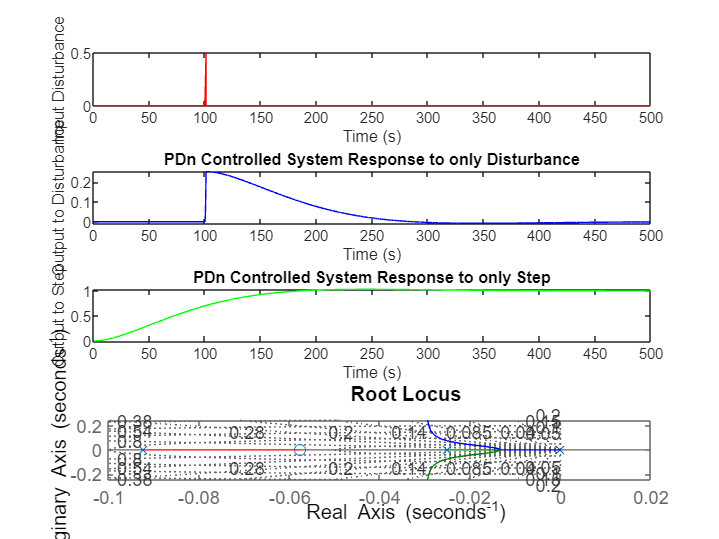


% Time domain analysis with new PD controller
PDn_closed_loop_D = minreal((G_open_loop_D) / (1 + PDn * G_open_loop_U));
[output_D_PDn, ~] = lsim(PDn_closed_loop_D, input_D, time); 
[output_U_PDn, ~] = lsim(PDn_closed_loop_U, input, time);
output_total_PDn = output_U_PDn + output_D_PDn;

% Plot results
figure;
subplot(4, 1, 1);
plot(time, input_D, 'r');
xlabel('Time (s)');
ylabel('Input Disturbance');

subplot(4, 1, 2);
plot(time, output_D_PDn, 'b');
xlabel('Time (s)');
ylabel('Output to Disturbance');
title('PDn Controlled System Response to only Disturbance');

subplot(4, 1, 3);
plot(time, output_U_PDn, 'g');
xlabel('Time (s)');
ylabel('Output to Step');
title('PDn Controlled System Response to only Step');

subplot(4, 1, 4);
plot(time, output_total_PDn, 'k');
xlabel('Time (s)');
ylabel('Total Output');
title('PDn Controlled System Response to Step Input and Sawtooth Input');

% Root locus with new PD controller
rlocus(PDn_open_loop_U);
sgrid;

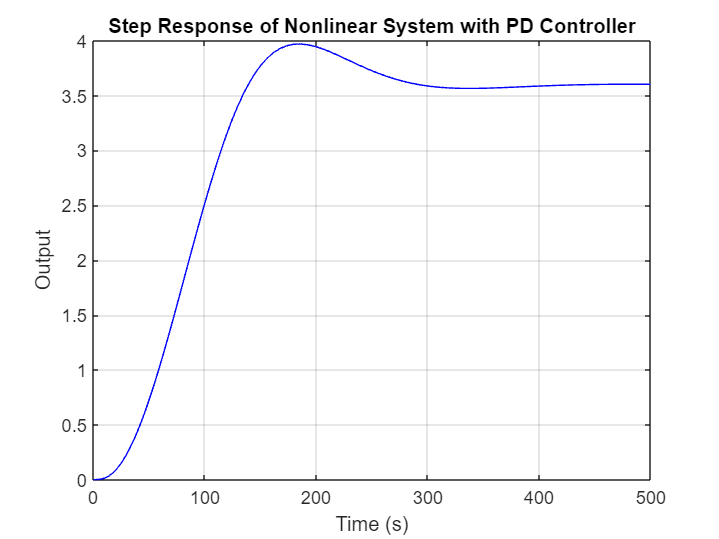


% Nonlinear system simulation
nonlinear_system = @(t, x, u) [
    -P1 * x(1) - x(1) * x(2) - Gb * x(2) + u(2);
    -P2 * x(2) + P3 * x(3);
    -n * x(3) - n * Ib + (1 / V) * u(1)
];

setpoint = 1;

pd_controller = @(x, dx) [
    Kpp * (setpoint - x(1)) - Kdd * dx(1);
    0
];

tspan = [0 500];        
x0 = [0; 0; 0];

odefun = @(t, x) nonlinear_system(t, x, pd_controller(x, [
    -P1 * x(1) - x(1) * x(2) - Gb * x(2);
    -P2 * x(2) + P3 * x(3);
    -n * x(3) - n * Ib
]));

[t, X] = ode45(odefun, tspan, x0);

% Plot nonlinear system response
figure;
plot(t, X(:, 1), 'b');
grid on;
xlabel('Time (s)');
ylabel('Output');
title('Step Response of Nonlinear System with PD Controller');


% Performance metrics for nonlinear system
response = X(:, 1);
final_value = response(end);
tolerance = 0.02 * abs(final_value);

ss_error = abs(final_value - setpoint);
[max_value, max_index] = max(response);
overshoot = ((max_value - final_value) / final_value) * 100;

peak_time = t(max_index);

for i = 1:length(t)
    if abs(response(i) - final_value) <= tolerance
        settling_time = t(i);
        break;
    end
end

fprintf('Performance Metrics:\n');

Performance Metrics:


fprintf('Steady-State Error: %.4f\n', ss_error);

Steady-State Error: 2.6037


fprintf('Overshoot: %.2f%%\n', overshoot);

Overshoot: 10.16%


fprintf('Settling Time: %.4f seconds\n', settling_time);

Settling Time: 140.0036 seconds


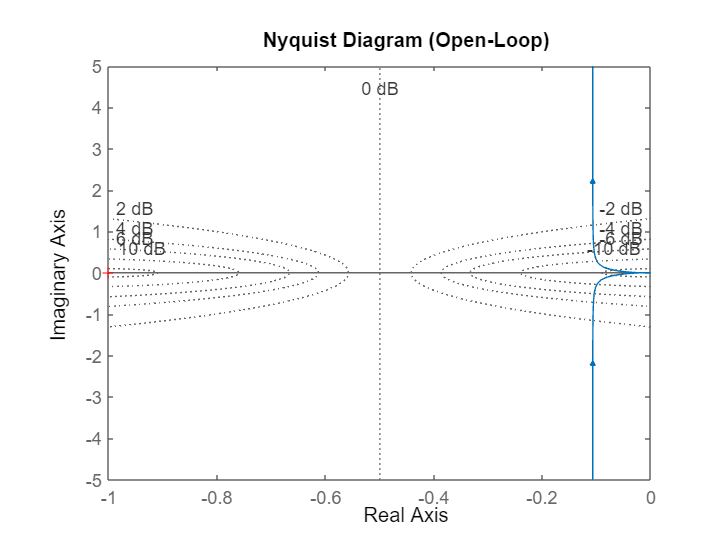


% Nyquist and Bode plots for open-loop system
figure;
nyquist(G_open_loop_U);
title('Nyquist Diagram (Open-Loop)');
grid on;

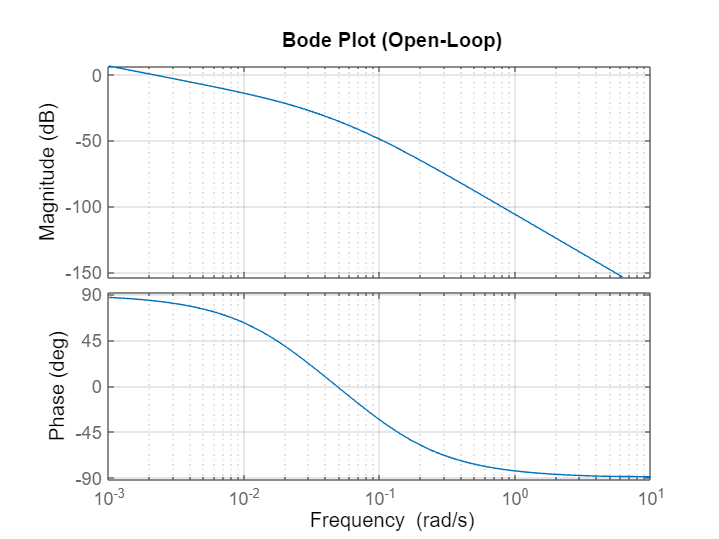


figure;
bode(G_open_loop_U);
title('Bode Plot (Open-Loop)');
grid on;


% Gain and phase margins
margins = allmargin(G_open_loop_U);
Gm_linear = margins.GainMargin;
Gm_dB = 20*log10(Gm_linear); 
Gm_frequencies = margins.GMFrequency;
Pm_degrees = margins.PhaseMargin;
Pm_frequencies = margins.PMFrequency;

[Gm, Pm, Wcg, Wcp] = margin(-G_open_loop_U);
fprintf('Achieved Gain Margin: %.2f dB\n', 20*log10(Gm));

Achieved Gain Margin: 34.89 dB


fprintf('Achieved Phase Margin: %.2f degrees\n', Pm);   

Achieved Phase Margin: 83.88 degrees


disp('Uncontrolled System:');

Uncontrolled System:


disp('Gain Margins (dB) and Frequencies:');

Gain Margins (dB) and Frequencies:


for i = 1:length(Gm_dB)
    fprintf('GM: %7.2f dB   at ω = %7.4f rad/s\n', Gm_dB(i), Gm_frequencies(i));
end
disp('-----------------------------');

-----------------------------


disp('Phase Margins (degrees) and Frequencies:');

Phase Margins (degrees) and Frequencies:


for i = 1:length(Pm_degrees)
    fprintf('PM: %7.2f°    at ω = %7.4f rad/s\n', Pm_degrees(i), Pm_frequencies(i));
end

PM:  -96.12°    at ω =  0.0021 rad/s


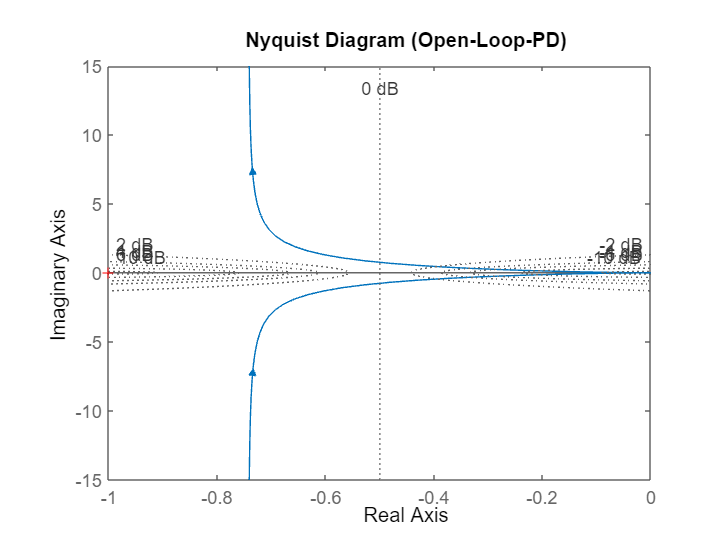


% Nyquist plot for PD controlled system
figure;
nyquist(PD_open_loop_U);
title('Nyquist Diagram (Open-Loop-PD)');
grid on;


% Gain and phase margins for PD controlled system
margins = allmargin(PD_open_loop_U);
Gm_linear = margins.GainMargin;
Gm_dB = 20*log10(Gm_linear); 
Gm_frequencies = margins.GMFrequency;
Pm_degrees = margins.PhaseMargin;
Pm_frequencies = margins.PMFrequency;

disp('PD Controlled System:');

PD Controlled System:


disp('Gain Margins (dB) and Frequencies:');

Gain Margins (dB) and Frequencies:


for i = 1:length(Gm_dB)
    fprintf('GM: %7.2f dB   at ω = %7.4f rad/s\n', Gm_dB(i), Gm_frequencies(i));
end

GM:     Inf dB   at ω =     Inf rad/s


disp('-----------------------------');

-----------------------------


disp('Phase Margins (degrees) and Frequencies:');

Phase Margins (degrees) and Frequencies:


for i = 1:length(Pm_degrees)
    fprintf('PM: %7.2f°    at ω = %7.4f rad/s\n', Pm_degrees(i), Pm_frequencies(i));
end

PM:   58.43°    at ω =  0.0164 rad/s



% Lead compensator design
T = 1357.9;
a = 0.123;
K1 = -2.25e-5;
lead = K1 * tf([1 1/T], [1 1/(a*T)])^3;
G_open_loop_lead = lead * G_open_loop_U;
G_closed_loop_lead = feedback(G_open_loop_lead, 1);

% Gain and phase margins for lead compensated system
margins = allmargin(G_open_loop_lead);
Gm_linear = margins.GainMargin;
Gm_dB = 20*log10(Gm_linear); 
Gm_frequencies = margins.GMFrequency;
Pm_degrees = margins.PhaseMargin;
Pm_frequencies = margins.PMFrequency;

disp('Lead Controlled System:');

Lead Controlled System:


disp('Gain Margins (dB) and Frequencies:');

Gain Margins (dB) and Frequencies:


for i = 1:length(Gm_dB)
    fprintf('GM: %7.2f dB   at ω = %7.4f rad/s\n', Gm_dB(i), Gm_frequencies(i));
end

GM:  133.39 dB   at ω =  0.0647 rad/s


disp('-----------------------------');

-----------------------------


disp('Phase Margins (degrees) and Frequencies:');

Phase Margins (degrees) and Frequencies:


for i = 1:length(Pm_degrees)
    fprintf('PM: %7.2f°    at ω = %7.4f rad/s\n', Pm_degrees(i), Pm_frequencies(i));
end

PM:   90.00°    at ω =  0.0000 rad/s


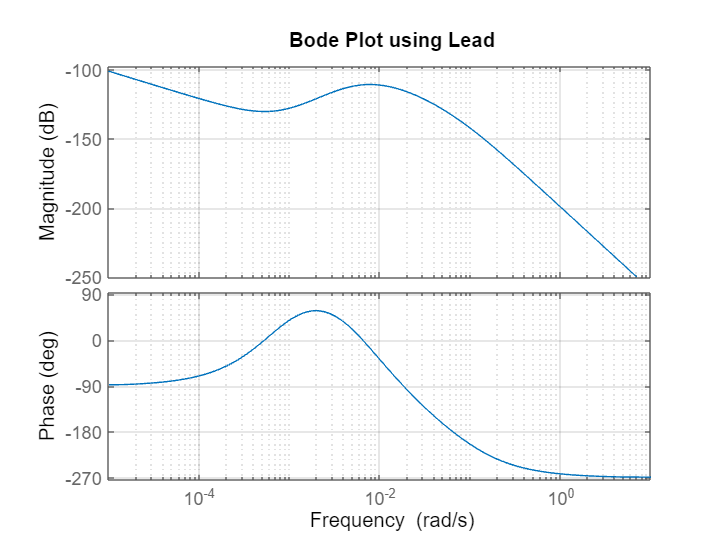


% Bode plot and step response for lead compensated system
figure;
bode(G_open_loop_lead);
title('Bode Plot using Lead');
grid on;

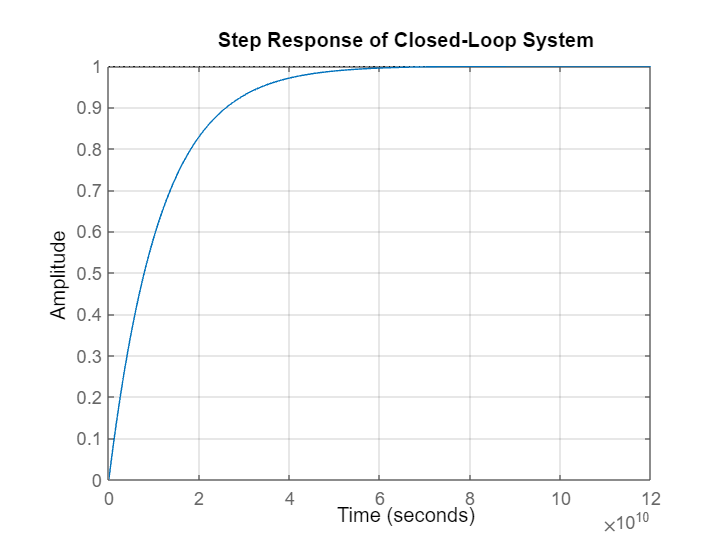


figure;
step(G_closed_loop_lead);
title('Step Response of Closed-Loop System');
grid on;


info = stepinfo(G_closed_loop_lead);
overshoot = info.Overshoot; 
settling_time = info.SettlingTime;
disp(['Overshoot: ', num2str(overshoot), '%']);

Overshoot: 0%


disp(['Settling Time: ', num2str(settling_time), ' s']);

Settling Time: 44242892021.1131 s


steady_state_value = dcgain(G_closed_loop_lead);
ess = 1 - steady_state_value;
disp(['Steady-State Error: ', num2str(ess)]);

Steady-State Error: 0



% Proportional controller design
K2 = -5;
G_open_loop_p = K2 * G_open_loop_U;
G_closed_loop_p = feedback(G_open_loop_p, 1);

% Gain and phase margins for proportional controlled system
margins = allmargin(G_open_loop_p);
Gm_linear = margins.GainMargin;
Gm_dB = 20*log10(Gm_linear); 
Gm_frequencies = margins.GMFrequency;
Pm_degrees = margins.PhaseMargin;
Pm_frequencies = margins.PMFrequency;

disp('Proportional Controlled System:');

Proportional Controlled System:


disp('Gain Margins (dB) and Frequencies:');

Gain Margins (dB) and Frequencies:


for i = 1:length(Gm_dB)
    fprintf('GM: %7.2f dB   at ω = %7.4f rad/s\n', Gm_dB(i), Gm_frequencies(i));
end

GM:   20.92 dB   at ω =  0.0480 rad/s


disp('-----------------------------');

-----------------------------


disp('Phase Margins (degrees) and Frequencies:');

Phase Margins (degrees) and Frequencies:


for i = 1:length(Pm_degrees)
    fprintf('PM: %7.2f°    at ω = %7.4f rad/s\n', Pm_degrees(i), Pm_frequencies(i));
end

PM:   62.59°    at ω =  0.0098 rad/s


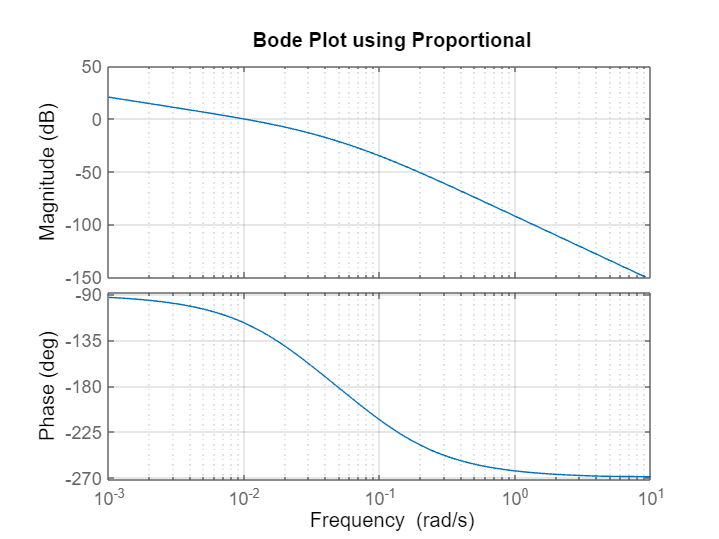


% Bode plot and step response for proportional controlled system
figure;
bode(G_open_loop_p);
title('Bode Plot using Proportional');
grid on;

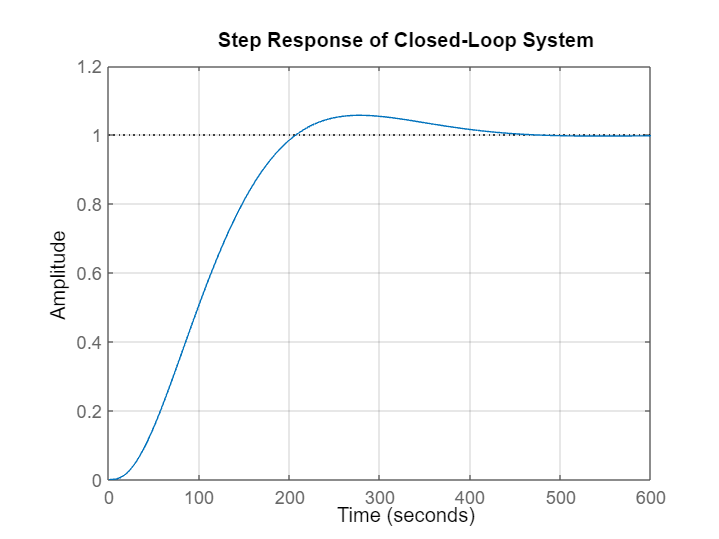


figure;
step(G_closed_loop_p);
title('Step Response of Closed-Loop System');
grid on;


info = stepinfo(G_closed_loop_p);
overshoot = info.Overshoot; 
settling_time = info.SettlingTime;
disp(['Overshoot: ', num2str(overshoot), '%']);

Overshoot: 5.6976%


disp(['Settling Time: ', num2str(settling_time), ' s']);

Settling Time: 387.8161 s


steady_state_value = dcgain(G_closed_loop_lead);
ess = 1 - steady_state_value;
disp(['Steady-State Error: ', num2str(ess)]);

Steady-State Error: 0
